load MotorY_WO_PID.mat
t_Y_WO = out.tout;
input_Y_WO = out.simout4;
error_Y_WO = out.simout5;
CE_Y_WO = out.simout6;
offset = 2.5;
output_Y_WO = out.simout7-offset;

GY = 3;
CE_Y_WO= (11.4/255)*GY*CE_Y_WO;


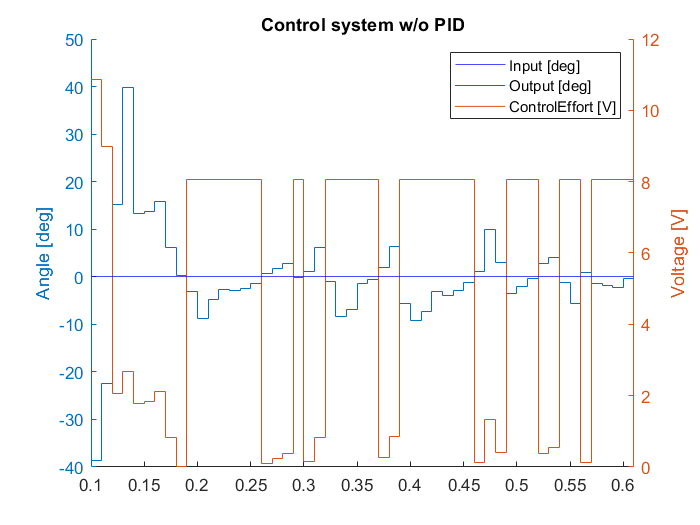

clf;
hold on
yyaxis left
yline(0,'b')
plot(output_Y_WO)
ylabel('Angle [deg]')
ylim([-40 50])


yyaxis right
plot(CE_Y_WO)
ylabel('Voltage [V]')
xlim([0.1 0.61])

title('Control system w/o PID')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off